# **Filtro de Kalman**

Considere que el sistema mecánico del ejercicio 1 está afectado por ruido según el modelo,

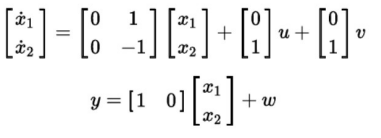

Los ruidos de proceso v y de medición w son gaussianos de media cero y varianzas Rv=0.1 y Rw=0.01. El ruido de proceso solo afecta a uno de los 2 estados, x2, esto debe ser incorporado en la solución de la ecuación de Riccati. 

**1)** Encuentre el valor de la matriz de covarianza P al resolver la ecuación de Ricatti correspondiente. 

close all; clear all; clc;
% Definimos las matrices del sistema.
A = [0  1;
     0 -1];
B = [0;
     1];
C = [1 0];
D = 0;
Rv = 0.1;
Rw = 0.01;

[L,P,E] = lqr(A',C',[0 0;0 Rv],Rw); % E son los polos del observador a lazo cerrado.
P

P =     0.0171    0.0146
    0.0146    0.0394


E

E =   -1.3532 + 1.1537i
  -1.3532 - 1.1537i


**2)** Encuentre el valor de la matriz de ganancia de observación L.

L

L =     1.7064    1.4559


**3)** Si se aumenta el ruido de proceso Rv, qué pasa con polos del estimador a lazo cerrado (sI-A+LC), ¿Se vuelven más rápidos, más lentos o no varían?.

Rv = 0.5;
[P,E,L] = care(A',C',[0 0;0 Rv],Rw);
E

E =   -1.9456 + 1.8126i
  -1.9456 - 1.8126i


Observamos que el hecho de aumentar el ruido del proceso hace que los polos se vuelvan más rápidos.